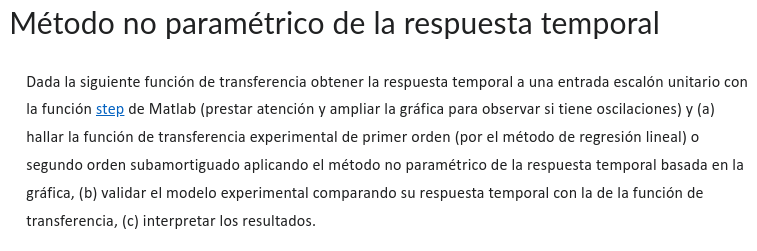

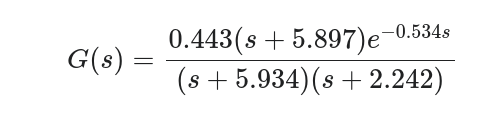

G = zpk([-5.897],[-5.934 -2.242],0.443,'InputDelay',0.534)

G =
 
                   0.443 (s+5.897)
  exp(-0.53*s) * -------------------
                 (s+5.934) (s+2.242)
 
Continuous-time zero/pole/gain model.



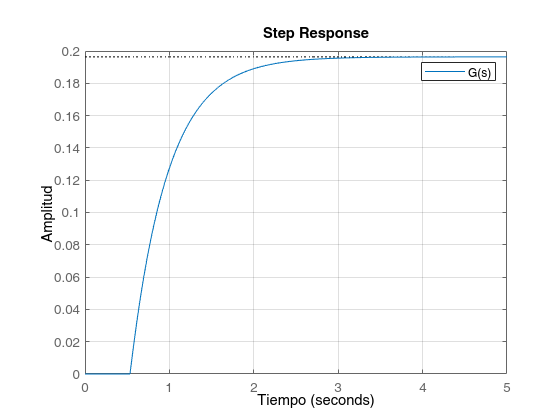

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 5;
figure()
clf
step(G,tiempofinal)
grid on
legend({'G(s)'}) 
xlabel('Tiempo')
ylabel('Amplitud')

#### Metodo de Regresión Lineal

[y,t] = step(G,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1) %valor de k según la fórmula

k = 0.1964

k = 0.1964

k = 0.1964


[p,s] = polyfit(tvalores,log(1-yvalores/(k)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',abs(tau))%función de transferencia resultante

tfEstimada =
 
                     0.1964
  exp(-0.362*s) * ------------
                  0.5067 s + 1
 
Continuous-time transfer function.



#### Validación

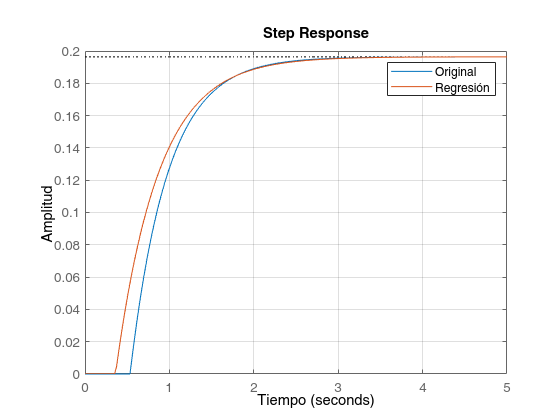

clf
figure(2)
step(G,tiempofinal)
grid on
hold on
step(tfEstimada)
legend({'Original','Regresión'})
xlabel('Tiempo')
ylabel('Amplitud')

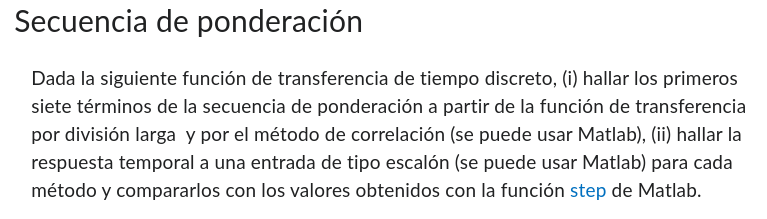

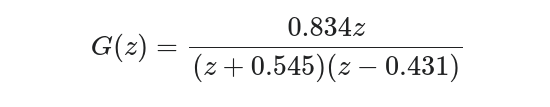

tf(zpk(0,[-0.545 0.431],0.834))

ans =
 
         0.834 s
  ----------------------
  s^2 + 0.114 s - 0.2349
 
Continuous-time transfer function.



clear;clc;close all
N = 1000 %número de muestras

N = 1000

M = 7;%Longitud secuencia de ponderación 
num=[-0.834];%numerador de la tf
den=[-1 -0.114 0.2349];%denominador de la tf

tf1=tf(num,den,1)%función de transferencia objetivo

tf1 =
 
          0.834
  ----------------------
  z^2 + 0.114 z - 0.2349
 
Sample time: 1 seconds
Discrete-time transfer function.



u=2*(prbs(5,N,[1 0 1 0 0])-0.5);%señal prbs de N datos con valores entre -1 y 1
xdata=0:1:N-1;%instantes de muestreo

[y,t]=lsim(tf1,u,xdata);%simulación del modelo con la entrada diseñada

[cyu,lagsyu] = xcorr(y,u,M-1);%M elementos de la correlación entre y y u
[cu,lagsu] = xcorr(u,0);   %correlación de la entrada con ella misma en el instante 0
tf_est=cyu(lagsyu>=0)./(N:-1:N-M+1)'/(cu/N); %fórmula para la secuencia de ponderación

delay=length(den)-length(num);%cálculo del retardo del sistema
tf_real=ldiv([1],[1 0.5],M-delay);%cálculo de la secuencia de ponderación
tf_real=[zeros(1,delay) tf_real];%adición del retardo a la secuencia de ponderación

pdata=0:1:M-1;
figure(1)
clf

stem(pdata,tf_real)%secuencia estimada
hold on
stem(pdata,tf_est)%secuencia real
title(['Respuesta al impulso '])
xlabel('Tiempo')
ylabel('Amplitud')
legend({'Original','Metodo de correlación'})

tf_est'

ans =    -0.0332   -0.0300    0.8297   -0.1293    0.1795   -0.0770    0.0263


tf_real

tf_real =          0         0    1.0000   -0.5000    0.2500   -0.1250    0.0625


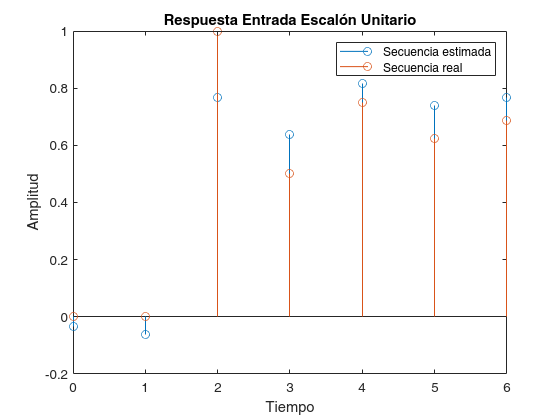

figure(2)
clf
response=cumsum(tf_est.*ones(length(tf_est),1));%convolución a la entrada de tipo escalón para la secuencia estimada
stem(pdata,response)
hold on
response2=cumsum(tf_real'.*ones(length(tf_est),1));%convolución a la entrada de tipo escalón para la secuencia real
stem(pdata,response2)
title("Respuesta Entrada Escalón Unitario")
legend({'Secuencia estimada', 'Secuencia real'})
xlabel('Tiempo')
ylabel('Amplitud')